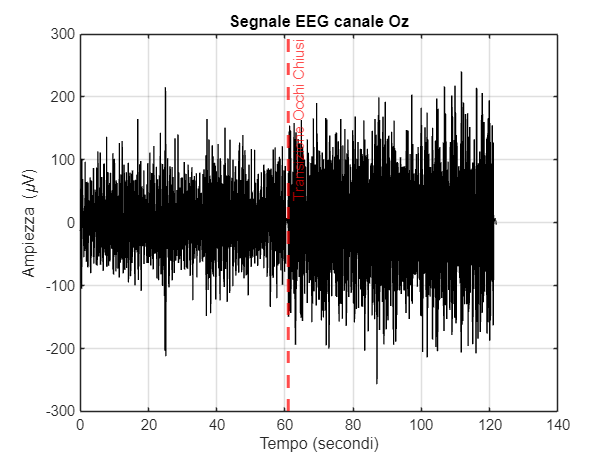


% Definiamo gli URL diretti ai file sul server di PhysioNet
url_run1 = 'https://archive.physionet.org/pn4/eegmmidb/S001/S001R01.edf';
url_run2 = 'https://archive.physionet.org/pn4/eegmmidb/S001/S001R02.edf';

file1 = 'S001R01.edf';
file2 = 'S001R02.edf';

options = weboptions('Timeout',60);   % aspetta fino a 60 secondi perchè il sito è lento e i classici 5 secondi non bastavano

% Controlla se i file esistono già, altrimenti li scarica
if ~isfile(file1)
    disp(['Scaricamento di ', file1, ' in corso... (potrebbe volerci qualche secondo)']);
    websave(file1, url_run1);
    disp('Download completato!');
end

if ~isfile(file2)
    disp(['Scaricamento di ', file2, ' in corso...']);
    websave(file2, url_run2);
    disp('Download completato!');
end

% Run 1 = Occhi Aperti (Baseline 1)
% Run 2 = Occhi Chiusi (Baseline 2)

% La funzione edfread crea una "timetable" 
[data_open, ~]   = edfread(file1);
[data_closed, ~] = edfread(file2);

%data_open.Properties.VariableNames; %mi serve per capire come matlab rinomina il tutto


% Il ritmo Alfa (8-12 Hz) reagisce alla chiusura degli occhi ed è 
% massimamente visibile sul lobo occipitale (canali O1, O2, Oz).


% Estrazione del canale Oz che matlab ha rinominato Oz__ e conversione in un vettore numerico
y_open = vertcat(data_open.Oz__{:});
y_closed = vertcat(data_closed.Oz__{:});

%per capire i problemi dato che questo tipo di file non mi dava i dati in
%vettori numerici
% class(y_open)
% 
% size(y_open)
% 
% y_open(1)
% 
% class(data_open.Oz__)

% Uniamo i due segnali per creare una transizione finta a metà:
% Prima metà = Occhi aperti (ERD, basso Alfa)
% Seconda metà = Occhi chiusi (ERS, alto Alfa)
y_raw = [y_open; y_closed];

% Otteniamo la frequenza di campionamento (PhysioNet usa 160 Hz)
fs = 160; 
N = length(y_raw);
t_asse = (0:N-1) / fs; % Asse dei tempi in secondi

%prima di applicare kalman si va a fare una pulizia del segnale 


%Rimozione della media (Detrending)
% I modelli AR assumono segnali a media nulla
%parlo di modelli AR perchè useremo kalman filter e smoother per la stima
%dei parametri 
y_centered = y_raw - mean(y_raw);

%Filtraggio Bandpass (1 - 40 Hz)
% Elimino le derive lentissime (sudore/respiro) e il rumore ad alta frequenza
y_clean = bandpass(y_centered, [1 40], fs);

%%PLOT
figure('Name', 'EEG Pre-processato (Occhi Aperti -> Chiusi)');
plot(t_asse, y_clean, 'k');
xline(length(y_open)/fs, 'r--', 'Transizione Occhi Chiusi', 'LineWidth', 2);
xlabel('Tempo (secondi)');
ylabel('Ampiezza (\muV)');
title('Segnale EEG canale Oz');
grid on;

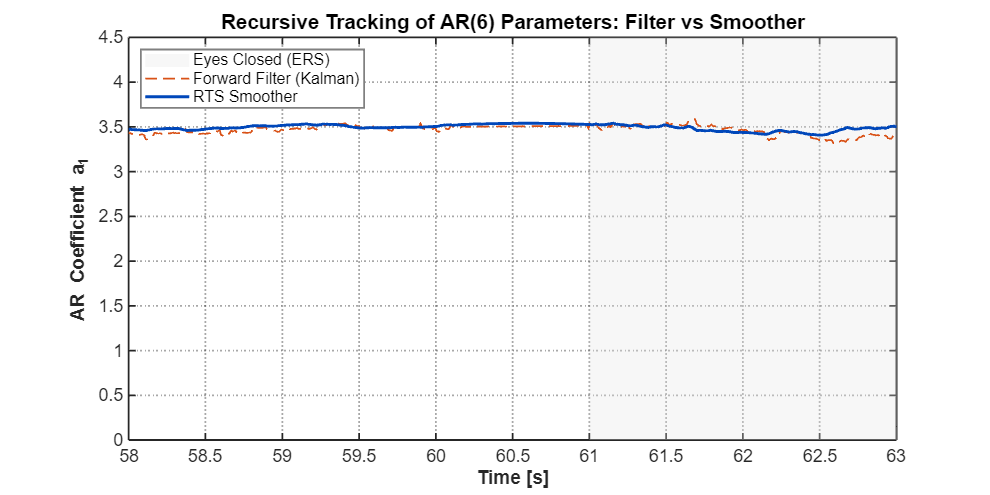

y = y_clean; % Questo è il vettore osservazioni reale

%p = 2
%provo ad aumentare l'ordine del modello perchè con p = 2 non si ha una
%buona visualizzazione di quello che accade
p = 6;
x = zeros(p, 1);           % Stima parametri AR 
P = eye(p);                % Covarianza dell'errore di stima
%Q = 0.0001 * eye(p);       % Rumore di processo 
%riduco Q perchè è come se mi fidassi maggiormente del processo, questa
%considerazione è stata fatta dopo aver osservato maggiore rumore
%proveniente dalle misurazioni
% Q = 1e-4 * eye(p);
Q = 1e-6 * eye(p);
%R = 0.01;                  % Rumore di misura 
%mentre aumento P perchè mi fido meno delle misurazioni che come si è visto
%sono molto rumorose
R = 0.1;
A = eye(p);                % A = I (i parametri AR sono costanti) o molto molto lenti

% ci serve salvare le info per poi darle in pasto allo smoother 
m_saved = zeros(p, N);
P_saved = zeros(p, p, N);

m_pred_saved = zeros(p, N);
P_pred_saved = zeros(p, p, N);

%bisogna fare un piccolo cambiamento rispetto a p = 2, ora H deve contenere
%i campioni passati da 1 a p

H = zeros(1,p);

%implementiamo il filtro di kalman con qualche distinzione rispetto agli
%esempi visualizzati in aula, perchè questa volta questo serve per stimare
%dei coefficienti

K_saved = zeros(p, N); % Matrice per salvare il guadagno di Kalman (6 x N)
e_saved = zeros(1, N); % Vettore per salvare l'innovazione (1 x N)

for k = (p+1):N
    %H dipende dai dati reali in quell'istante
    %H = [y(k-1), y(k-2)]; 

    for i = 1:p
        H(i) = y(k-i);
    end
    
    %Time update
    x_pred = A * x;
    P_pred = A * P * A' + Q;
    
    innovazione = y(k) - (H * x_pred);
    S = H * P_pred * H' + R;      
    K = P_pred * H' / S;           % Guadagno di Kalman
    
    x = x_pred + K * innovazione;  % Aggiornamento stato
    P = (eye(p) - K * H) * P_pred; % Aggiornamento covarianza
    
    K_saved(:, k) = K; 
    e_saved(k) = innovazione;

    %salvo i dati per lo smoother 
    m_saved(:, k) = x;
    P_saved(:, :, k) = P;

    m_pred_saved(:, k) = x_pred; 
    P_pred_saved(:, :, k) = P_pred;

end

% Inizializzazione smoother
m_smoothed = zeros(p, N);
P_smoothed = zeros(p, p, N);

% L'ultimo punto è uguale a quello filtrato
m_smoothed(:, N) = m_saved(:, N);
P_smoothed(:, :, N) = P_saved(:, :, N);

% Backward pass (da N-1 fino a p+1)
for k = (N-1):-1:(p+1)
    %calcolo del guadagno di smoothing (G)
    %G = P_k * A' * inv(P_pred_k+1)
    G = P_saved(:, :, k) * A' / P_pred_saved(:, :, k+1);
    
    %Aggiornamento media smussata
    m_smoothed(:, k) = m_saved(:, k) + G * (m_smoothed(:, k+1) - m_pred_saved(:, k+1));
    
    %Aggiornamento covarianza smussata
    P_smoothed(:, :, k) = P_saved(:, :, k) + G * (P_smoothed(:, :, k+1) - P_pred_saved(:, :, k+1)) * G';
end

%plot del confronto

fig1 = figure('Name', 'Confronto Stima AR', 'Color', 'w'); 
fig1.Position = [100, 100, 900, 450]; 

col_filter = [0.85, 0.32, 0.09]; 
col_smooth = [0.0, 0.28, 0.73];  

hold on;
t_transizione = length(y_open)/fs;
xregion(t_transizione, t_asse(end), 'FaceColor', [0.9 0.9 0.9], 'EdgeColor', 'none', 'DisplayName', 'Eyes Closed (ERS)');

plot(t_asse, m_saved(1, :), '--', 'Color', col_filter, 'LineWidth', 1.2, 'DisplayName', 'Forward Filter (Kalman)');
plot(t_asse, m_smoothed(1, :), '-', 'Color', col_smooth, 'LineWidth', 2.0, 'DisplayName', 'RTS Smoother');

ax = gca;
ax.FontSize = 12; ax.FontName = 'Arial'; ax.LineWidth = 1.2; 
ax.GridLineStyle = ':'; ax.GridAlpha = 0.4; 
grid on; box on;

xlabel('Time [s]', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('AR Coefficient a_1', 'FontSize', 13, 'FontWeight', 'bold');
title('Recursive Tracking of AR(6) Parameters: Filter vs Smoother', 'FontSize', 14);

lgd = legend('show'); lgd.Location = 'northwest'; lgd.EdgeColor = [0.5 0.5 0.5];
xlim([58, 63]); 
ylim([0, 4.5]); % Aggiustato leggermente per l'AR(6)

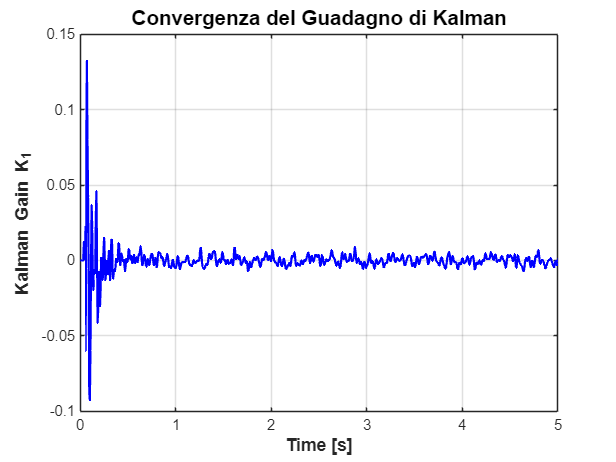



%per la convergenza 
figure('Name', 'Convergenza Guadagno K', 'Color', 'w');
% Plottiamo il primo elemento del vettore K (relativo al parametro a_1)
plot(t_asse, K_saved(1, :), 'b', 'LineWidth', 1.5);
grid on;

% Zoom sui primi 5 secondi per vedere il transitorio iniziale
xlim([0, 5]); 

xlabel('Time [s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Kalman Gain K_1', 'FontSize', 12, 'FontWeight', 'bold');
title('Convergenza del Guadagno di Kalman', 'FontSize', 14);

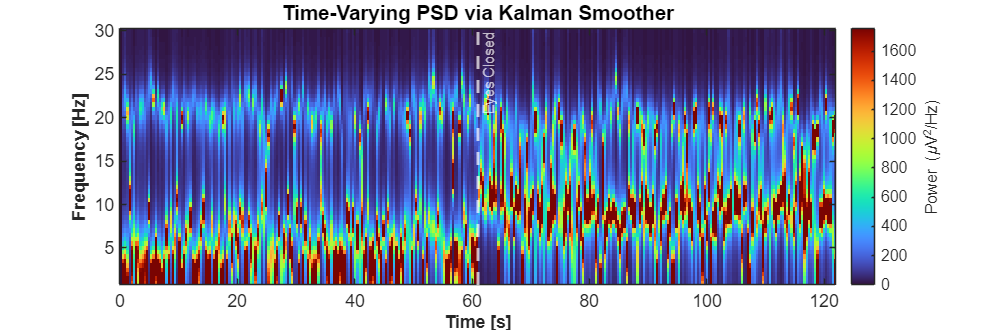


%%Spettrogramma
f_min = 1;   
f_max = 30;  
f_res = 0.5; 
f_axis = f_min:f_res:f_max;
num_f = length(f_axis);
PSD_matrix = zeros(num_f, N);

for k = 1:N
    a_coeffs = m_smoothed(:, k); 
    for fi = 1:num_f
        f = f_axis(fi);
        esponenti = exp(-1i * 2 * pi * f * (1:p)' / fs);
        den = 1 - sum(a_coeffs .* esponenti);
        PSD_matrix(fi, k) = 1 / (abs(den)^2);
    end
end

fig2 = figure('Name', 'Kalman Smoother Spectrum', 'Color', 'w');
fig2.Position = [100, 100, 900, 300]; 

imagesc(t_asse, f_axis, PSD_matrix);
axis xy; 
colormap(turbo);

% Limitazione della scala colori per saturare i picchi
p_lim = prctile(PSD_matrix(:), 92); 
clim([0, p_lim]);

hold on;
xline(t_transizione, 'w--', 'Eyes Closed', 'LineWidth', 2, 'LabelOrientation', 'aligned');

ax = gca;
ax.FontSize = 12; ax.FontName = 'Arial';
xlabel('Time [s]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequency [Hz]', 'FontSize', 12, 'FontWeight', 'bold');
title('Time-Varying PSD via Kalman Smoother', 'FontSize', 14);

cb = colorbar;
cb.Label.String = 'Power (\muV^2/Hz)';
cb.Label.FontSize = 11;

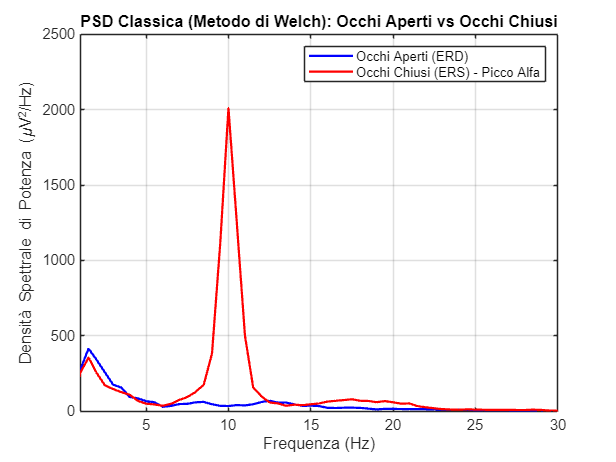


figure;
window = fs * 2; % Finestra di 2 secondi
noverlap = fs;   % Sovrapposizione del 50%

% Calcolo PSD Welch Occhi Aperti (primi 60s)
[pxx_open, f] = pwelch(y_clean(1:60*fs), window, noverlap, fs*2, fs);
% Calcolo PSD Welch Occhi Chiusi (ultimi 60s)
[pxx_closed, ~] = pwelch(y_clean(60*fs+1:end), window, noverlap, fs*2, fs);

% Plot in scala logaritmica (dB) o lineare, lineare rende il picco più evidente
plot(f, pxx_open, 'b', 'LineWidth', 1.5); hold on;
plot(f, pxx_closed, 'r', 'LineWidth', 1.5);
xlim([1 30]); % Zoom sulle frequenze cerebrali di interesse
xlabel('Frequenza (Hz)');
ylabel('Densità Spettrale di Potenza (\muV^2/Hz)');
title('PSD Classica (Metodo di Welch): Occhi Aperti vs Occhi Chiusi');
legend('Occhi Aperti (ERD)', 'Occhi Chiusi (ERS) - Picco Alfa');
grid on;